clearvars;
addpath("Spherical_Harmonics/");

### Initial parameter

f = 440; % Hz
c = 343; % m/s
k = 2*pi*f/c; % Wave number

## Active Noise Control using Spherical Harmonics

The sound pressure at a point $x\{r,\theta,\phi\}$ with respect to the origin can be expressed as


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


where

$C_{lm}(k)$ are the spherical harmonics coefficients,

$k=\frac{2\pi f}{c}$ is the wave number,

$f$ is the frequency,

$c$  is the speed of sound propagation

$j_l(kr)$ is the $l$th order Bessel function of the first kind,

$Y_{lm}(\theta,\phi)$ are the spherical harmonics.

#### Bessel function

l = 1, m = 1; r = 1; % Meaningless values for degree, order, radius

l = 1

J = besselj(l,k*r);

#### Spherical harmonics

The spherical harmonic of degree $l$ and order $m$ is given by


$$Y_{lm}(\theta,\phi) \equiv (-1)^m \sqrt{\frac{2l+1}{4\pi}\frac{(l-m)!}{(l+m)!}}P_l^m(\cos(\theta))e^{im\phi}$$


where 

$P_n^m(x)$ is the associated Legendre function, unnormalized.

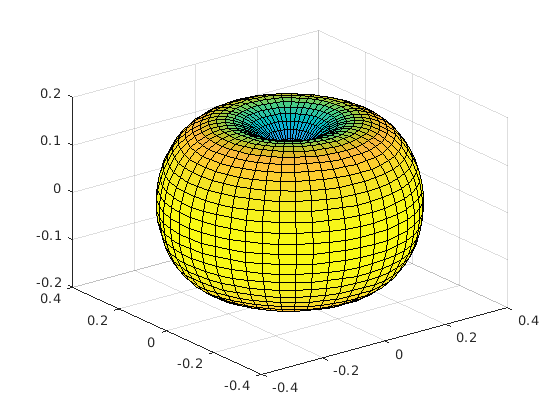

% create a 2D grid
th = linspace(0,pi,50);    % inclination
phi = linspace(0,2*pi,50); % azimuth
[th,phi] = meshgrid(th,phi);

% compute spherical harmonic of degree 3 and order 1
Y = harmonicY(l,m,th,phi);

% plot the magnitude
[x,y,z] = sph2cart(phi,pi/2-th,abs(Y));
surf(x,y,z,abs(Y));

### Approximation

The sound field can be approximated by


$$P(r,\theta,\phi,k) = \sum_{l=0}^L \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


where


$$L = \lceil \frac{ekr}{2} \rceil$$


$e$ is the natural exponential

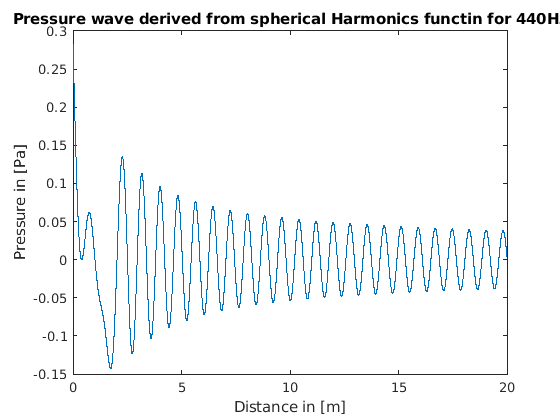

L = ceil(exp(1)*k*r/2);
C = ones(1,2*L*L);
C(5) = 1;
C(6) = 1;
i = 1;
th = 21;
phi = 22;
Rs = 20000;
Fs = 1000;
r = (0:Rs)/Fs;
P = zeros(1,size(r,2));
for l=0:L
    for m=-l:l
        P = P + C(i)*besselj(l,k*r)*harmonicY(l,m,th,phi);
        i = i + 1;
    end
end
figure;
plot(r, real(P));
title("Pressure wave derived from spherical Harmonics functin for " + f + "Hz")
xlabel("Distance in [m]");
ylabel("Pressure in [Pa]");

We are now able to calculate the resulting pressure for known coefficients $C_{lm}$.

### Harmonic Coefficients

We have 


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


By multiplying both side by $\overline\mathbf{Y}_{lm}$ and integrating over the sphere we get:


$$C_{lm}(k) = \frac{1}{\mathbf j_l(kr)}\int_0^\pi\int_0^{2\pi}P(r,\theta,\phi,k)\overline\mathbf{Y}_{lm}(\theta,\phi)d\theta d\phi$$


where $\overline\mathbf{Y}_{lm}$ is the complex conjugate matrix of $\mathbf{Y}_{lm}$

We try solving the double integral by running the formula in wolframscript:

wolfram strugles finding an answer as it is not able to calculate the spherical harmonics conjugate matrix for an infinite size.

However it is possible to find a solution to the formula for specific values for l and m

For example:


$$C_{00}(k) = \frac{1}{ j_0(kr)}\int_0^\pi\int_0^{2\pi}sin(kr)\overline{Y}_{00}(\theta,\phi)d\theta d\phi = \frac{\pi^{\frac{3}{2}}sin(kr)}{J_0(kr)}$$



$$C_{01}(k) = \frac{1}{\mathbf j_0(kr)}\int_0^\pi\int_0^{2\pi}sin(kr)\overline\mathbf{Y}_{01}(\theta,\phi)d\theta d\phi = \frac{\pi^{\frac{3}{2}}sin(kr)}{J_0(kr)}$$


### Harmonice Ceofficients for plane wave

[https://en.wikipedia.org/wiki/Plane-wave_expansion](https://en.wikipedia.org/wiki/Plane-wave_expansion)

A plane wave can be expressed as a linear combination of spherical waves:


$$e^{i\mathbf{k}\cdot \mathbf{r}} = 4\pi\sum_{l=0}^\infty\sum_{m=-l}^l i^l j_l(\mathbf{kr})Y_{lm}(\hat\mathbf k) \overline Y_{lm}(\hat\mathbf r)$$


where 

$i$  is the imaginary unit,

$\mathbf k$ is a wave vector of length $k$

$\mathbf r$ is a position vector or length $r$

$j_l$ are spherical Bessel functions,

$Y_{lm}$ are the spherical harmonics

$\overline Y_{lm}$ is the complex conjugate of $Y_{lm}$

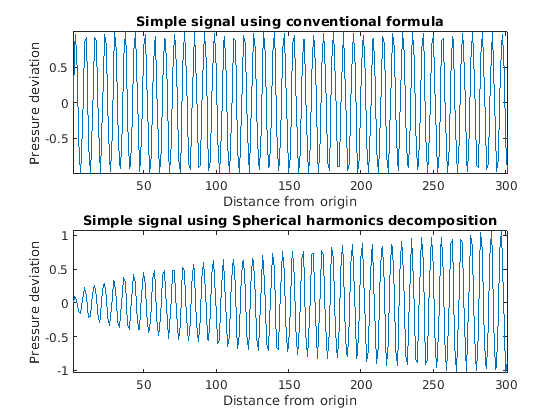

f = 5000; c = 343; k = 2*pi*f/c; 
r = 0:0.01:3;
L = ceil(exp(1)*k*r/2);
signal = exp(1i*k*r);
subplot(211);
plot(imag(signal));
title("Simple signal using conventional formula");
ylabel("Pressure deviation");
xlabel("Distance from origin");
axis tight;
% --------------------------------------------------------------
signal_harmonics = zeros(1,length(L));
h = waitbar(0,'Initializing waitbar...');
for i=1:length(L);
    waitbar(i/length(L),h,'Computing...')
        
    for l=0:L(i)
        for m=-l:l
            signal_harmonics(i) = signal_harmonics(i) + 1i^l*besselj(l,k*r(i))*harmonicY(l,m,0,0)*conj(harmonicY(l,m,0,0));
        end
    end
end
close(h);
subplot(212);
plot(imag(signal_harmonics));
title("Simple signal using Spherical harmonics decomposition");
ylabel("Pressure deviation");
xlabel("Distance from origin");
axis tight;

### Harmonic Coefficients - Spherical microphone array

The spherical harmonics coefficients can be calculated using


$$\mathbf{C}_{lm}(k) =  \frac{1}{\mathbf{j}_l(kR)} \sum_iP(R,\theta_i,\phi_i,k)\mathbf{Y}^*_{lm}(\theta_i,\phi_i)\gamma_i$$


where

$\theta_i$ is the elevation of the $i$th microphone,

$\phi_i$ is the azimuth angle of the $i$th microphone

$R$ is the radius of the spherical microphone array.

$P(R,\theta_i,\phi_i,k)$ is the pressure measured at the $i$th microphone for the wavenumber $k$

$\mathbf{Y}^*_{lm}(.)$ is the complex conjugated harmonics matrix

$\gamma_i$ are weights specific to the sampling scheme of the microphone array

l = 0:L;
m = -L:L;
Y = zeros(length(l),length(m));
